## Import the Data

Fall = table2struct(readtable('HW4FallData.xlsx', 'PreserveVariableNames', true));

Spring = table2struct(readtable('HW4SpringData.xlsx', 'PreserveVariableNames', true));

## Scrub the Data

% Creates cell arrays fallcell and springcell out of the structs of the data.
fallcell=struct2cell(Fall)';
[fr fc]=size(fallcell);
springcell=struct2cell(Spring)';
[sr sc]=size(springcell);


% Creates a new cell array students with the space to hold all students
% from fall and spring (fr+sr).
students=cell((fr+sr), 16);


% First places the data from the first 13 columns of fallcell into the first 
% 13 columns of students, so that up until the quiz grades, all "fields" are 
% the same ("fields" is in apostrophes because now that the data is in a 
% cell array, there are no longer fields).
% Next, the code initialized the 14th, 15th, and 16th columns as vectors 
% containing all quiz, class, and lab grades respectively.
for i=1:fr
    for j=1:13
        students{i, j}=fallcell{i, j};
    end
    students{i, 14}=[fallcell{i, 14:22}];
    students{i, 15}=[fallcell{i, 23:49}];
    students{i, 16}=[fallcell{i, 50:74}];
end


% Transfers the data from springcell into the new cell array students, but
% since the first 319 rows are already full from fallcell, the for loop
% starts at a higher value. 
% In addition, the spring data has one less quiz grade and lab grade,
% so this is accounted for.
for x=(fr+1):length(students)
    for j=1:13
        students{x, j}=springcell{x-319, j};
    end
    students{x, 14}=[springcell{x-319, 14:21}];
    students{x, 15}=[springcell{x-319, 22:47}];
    students{x, 16}=[springcell{x-319, 48:71}];
end


% Finds all instance of NaN in the data, and since these values cannot be
% used to compute course grade, the entire students that holds that NaN
% value is deleted.
z=1;
while(z<=length(students))
    for t=1:16
        if any(isnan(students{z, t}))
            students(z, :)=[];
        end
    end
    z=z+1;
end

## Exploratory Data Analysis

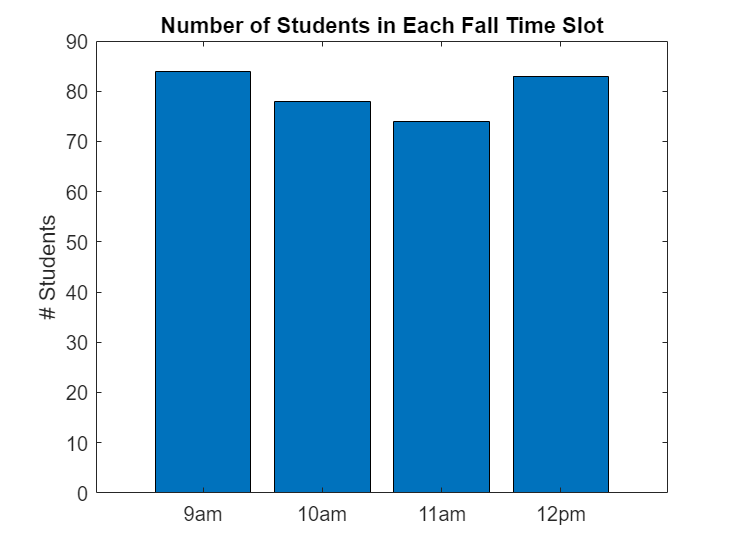

%% Exploratory Data Analysis
% Since the goals of this data analysis are not concerned with raw data points, 
% exploratory data analysis of the raw data points are irrelevant.
% However, we chose to show the number of students in each class time, 
% so that we can examine the sample sizes of our later analysis. 
% This was done with both semesters.
figure();

n=zeros(1,4);
n(1)=0;
n(2)=0;
n(3)=0;
n(4)=0;

for i=1:length(fallcell)
    if strcmp(fallcell{i,3}, '9am')
        n(1)=n(1)+1;
    elseif strcmp(fallcell{i,3}, '10am')
        n(2)=n(2)+1;
    elseif strcmp(fallcell{i,3}, '11am')
        n(3)=n(3)+1;
    elseif strcmp(fallcell{i,3}, '12pm')
        n(4)=n(4)+1;
    end
end

times=categorical({'9am','10am','11am','12pm'});
times=reordercats(times, {'9am','10am','11am','12pm'});
bar(times, n);
title('Number of Students in Each Fall Time Slot');
ylabel('# Students');

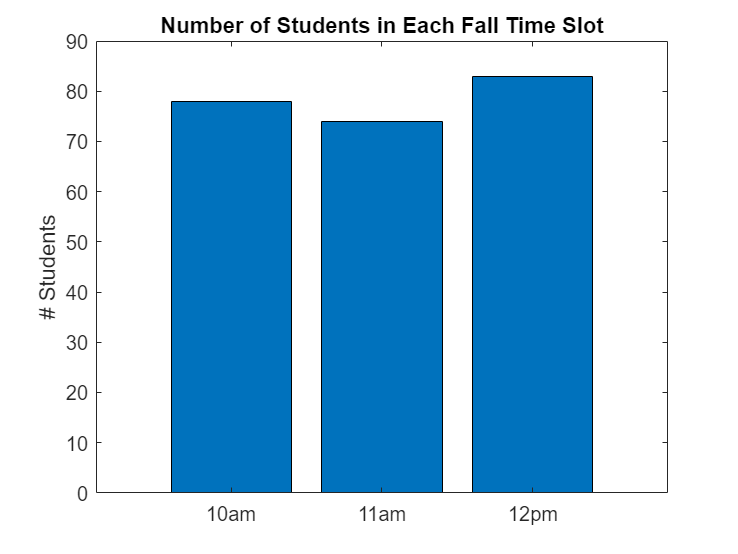

figure();

n=zeros(1,3);
n(1)=0;
n(2)=0;
n(3)=0;

for i=1:length(fallcell)
    if strcmp(fallcell{i,3}, '10am')
        n(1)=n(1)+1;
    elseif strcmp(fallcell{i,3}, '11am')
        n(2)=n(2)+1;
    elseif strcmp(fallcell{i,3}, '12pm')
        n(3)=n(3)+1;
    end
end

times=categorical({'10am','11am','12pm'});
times=reordercats(times, {'10am','11am','12pm'});
bar(times, n);
title('Number of Students in Each Fall Time Slot');
ylabel('# Students');

## Goals & Hypothesis

Our goal from this assignment is to find out whether or not a higher class average has a positive correlation with a student's overall course grade.

We hypothesize that this correlation is in fact true, as going to more classes and getting good scores on participation and other elements usually means that one is better prepared for exams and projects.

Our second goal is to find which time period of the day is most conducive to learning EK125.

We hypothesize that morning lectures, such as a 9:00 AM class, will lead to higher overall class and course grades due to the freshness of the students' minds.

## Data Analysis

% Creates empty vectors that will hold the average quiz, class, lab, and
% homework/project grades. These variables will be used in finding the
% total course grade later on.
avgQuiz=zeros(1, length(students));
avgClass=zeros(1, length(students));
avgLab=zeros(1, length(students));
avgHW=zeros(1, length(students));


% Fill in the data values for the average quiz, class, lab, and
% homework/project grades for every student into the respective vectors.
% Then the course grade is found using the proper weighting as given by the
% EK125 Course Information Sheet. These values are put into a new vector,
% called courseGrade
for i = 1:length(students)
    avgQuiz(i)=mean(students{i,14});
    avgClass(i)=mean(students{i,15});
    avgLab(i)=mean(students{i,16});
    avgHW(i)=(students{i,9}*2 + students{i,10}*5 + students{i,11}*10 + students{i,12}*10/3 + students{i,13}*10)/5;
end

courseGrade=zeros(1,length(students));

for i=1:length(students)
    courseGrade(i)=(avgQuiz(i)*10)*.15+(avgClass(i)*10)*.15+(avgLab(i)*10)*.15+(avgHW(i))*.15;
    courseGrade(i)=courseGrade(i)+students{i,6}*.1+students{i,7}*.15+students{i,8}*.15;
end

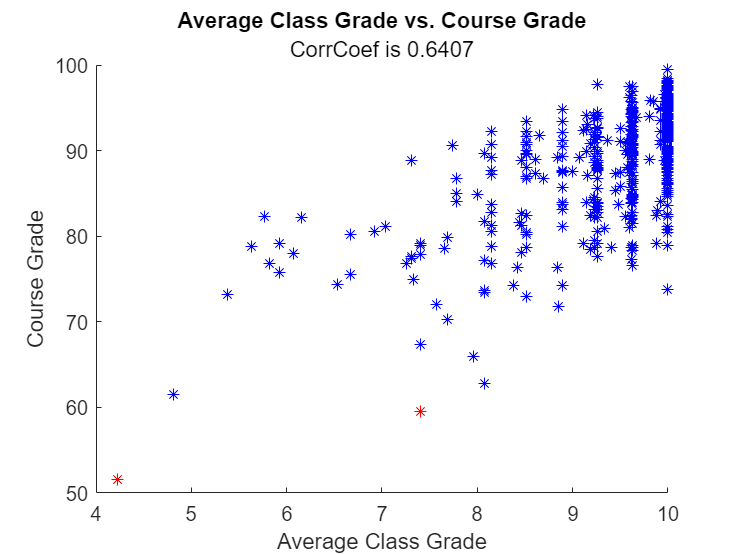

% The Average Class Grade is plotted against the Course Grade for every
% single individual. Each point represents one student, and the two red
% points are the only ones who failed the course (<60). In the title, we
% see the correlation coefficient of 0.6008.
figure();
hold on;

for i=1:484
    if courseGrade(i)>=60
        p='b*';
        plot(avgClass(i), courseGrade(i), p);
    elseif courseGrade(i)<60
        p='r*';
        plot(avgClass(i), courseGrade(i), p);
    end
end

axis([4 10 50 100]);
xlabel('Average Class Grade');
ylabel('Course Grade');

c=corrcoef(avgClass, courseGrade);
s=sprintf('CorrCoef is %.4f', c(2));
title('Average Class Grade vs. Course Grade', s);
hold off;

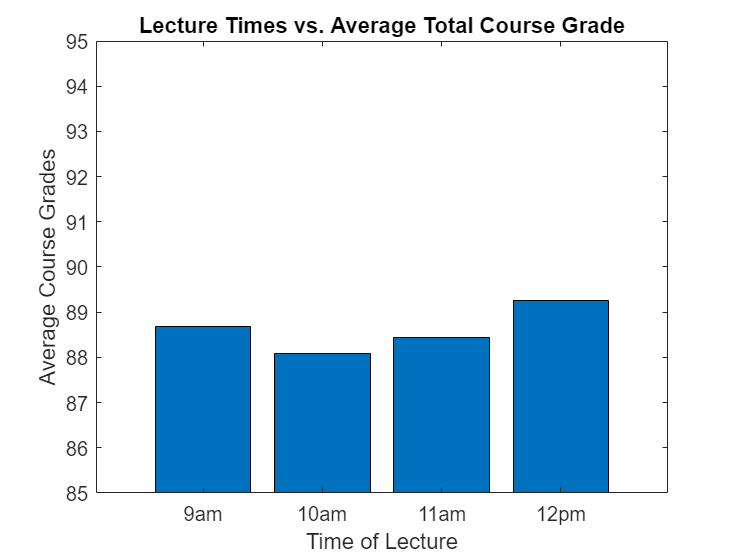

% Showed the effect of the time of lecture on the average total course
% grade. This was done by taking the average course grade for each lecture
% time slot, and then using the bar function to graph these into a neat bar
% graph.
timeCourseAvg=zeros(1,4);
[X9, ~]=find(strcmp(students, '9am'));
timeCourseAvg(1)=mean([courseGrade(X9')]);
[X10, ~]=find(strcmp(students, '10am'));
timeCourseAvg(2)=mean([courseGrade(X10')]);
[X11, ~]=find(strcmp(students, '11am'));
timeCourseAvg(3)=mean([courseGrade(X11')]);
[X12, ~]=find(strcmp(students, '12pm'));
timeCourseAvg(4)=mean([courseGrade(X12')]);

figure();

times=categorical({'9am', '10am', '11am', '12pm'});
times=reordercats(times, {'9am', '10am', '11am', '12pm'});
bar(times, timeCourseAvg);
ylim([85 95]);
title('Lecture Times vs. Average Total Course Grade');
ylabel('Average Course Grades');
xlabel('Time of Lecture');

## Conclusions

The conclusions that we were able to make were that average class (lecture) grade has no effect on the overall course grade of an individual students, and that time of lecture has almost no effect on an individuals course grade.

The first inference can be seen through the correlation coefficient of these data vectors, as the correlation coefficient is around 0.6008. This is low enough to see that there is very little correlation.

The second inference cn be seen by the fact that all 4 time slows for lectures had an average course grade tha differed by less than a single full point.